[robotArduino, rawRangeIn, blinkLED] = SETUPARDUINO('COM12');


lid = LIDAR('COM11')

lid =   LIDAR with properties:

        lidar: [1×1 serial]
     pol_data: []
    cart_data: []


data = lid.scan(10000)

  Columns 1 through 11

        1976        1986        1986        1999        4055           7        4055        2084        2056        2056        2056

  Columns 12 through 22

        2075        2114        4128        4135        4140        4140        4164        4170        4194        4197        4214

  Columns 23 through 33

        4214        4236        4256        4265        4265           0           7        1287        1269        1269        1269

  Columns 34 through 44

        1305           0           0           0           0           7        1457        1457          15        1457        1457

  Columns 45 through 55

           0           0           0           0           0           0           7           0           0           0           0

  Columns 56 through 66

           0           7           0           0           0           0           0           0           0           0           0

  Columns 67 through 77

           0          

data = 	1.0e+03 *

   -0.9880   -0.9824   -0.9718   -0.9674   -1.9406         0   -1.8967   -0.9635   -0.9393   -0.9281   -0.9168   -0.9138   -0.9193   -1.7723   -1.7523   -1.7314   -1.7082   -1.6948   -1.6738   -1.6598   -1.6373   -1.6201   -1.5962   -1.5804   -1.5636   -1.5425   -1.5180         0         0   -0.4358   -0.4224   -0.4150   -0.4077   -0.4116         0         0         0         0         0   -0.4083   -0.3997         0   -0.3825   -0.3739         0         0         0         0         0         0
   -1.7113   -1.7260   -1.7320   -1.7493   -3.5605         0   -3.5840   -1.8479   -1.8289   -1.8346   -1.8403   -1.8629   -1.9036   -3.7282   -3.7453   -3.7606   -3.7711   -3.8035   -3.8193   -3.8516   -3.8644   -3.8901   -3.9000   -3.9301   -3.9584   -3.9763   -3.9857         0         0   -1.2110   -1.1966   -1.1992   -1.2017   -1.2384         0         0         0         0         0   -1.3986   -1.4011         0   -1.4059   -1.4082         0         0         0         0

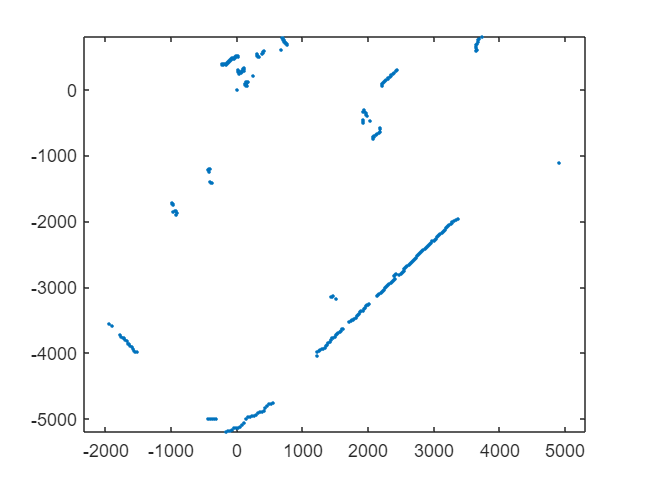

plot(data(1,:), data(2,:) , '.')
axis equal;

lid.close();

lid.cart_data


ans =

     []



fprintf(lid.lidar, 'QT');
fclose(lid.lidar);
clear lidar;
warning('on');
disp("the lidar has successfully been terminated")

clear
clc

camera = Camera();

camera.show()

while true
    
    imshow(camera.disp_tags())
    pause(1)
end

loc = camera.poses()

function [robotArduino, rawRangeIn, blinkLED] = SETUPARDUINO(COMPORT)
    robotArduino = arduino(COMPORT, 'Uno', 'Libraries', 'Servo');

    blinkLED = 'D13';
    configurePin(robotArduino, blinkLED, 'DigitalOutput');

    rawRangeIn = 'A3';
    configurePin(robotArduino, rawRangeIn, 'AnalogInput')

end